## PWM Modulator Demonstration

## Initialise

close all;
clear;
clc;

## Sine wave (as the I/P signal) generation

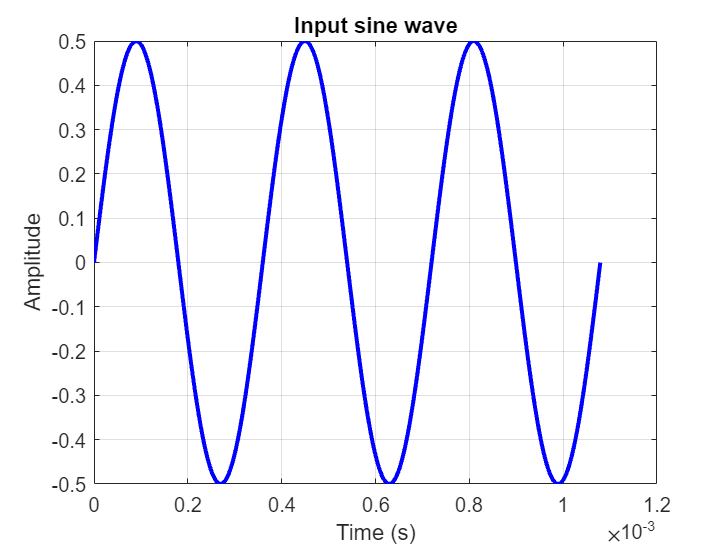

% Parameters
sineFrequency = 2780; % Frequency in Hz Default set as standard 1kHz
dispPeriod = 3;
sineSamplingRate = 10000* sineFrequency; % Sampling rate in Hz, 1000 points per cycle
sineNumPoints = dispPeriod * sineSamplingRate ./ sineFrequency; % Number of data points
t = (0:sineNumPoints-1) / sineSamplingRate;% Define time axis

sineAmplitude = 0.5; % Amplitude of Sine wave
sineWaveSignal = sineAmplitude * sin(2 * pi * sineFrequency * t); % Sine wave output

% % Plot the sine wave
figure();
plot(t, sineWaveSignal, "LineWidth", 2, "Color", "blue");
xlabel("Time (s)");
ylabel("Amplitude");
title("Input sine wave");
grid on;

## Sawtooth wave generation

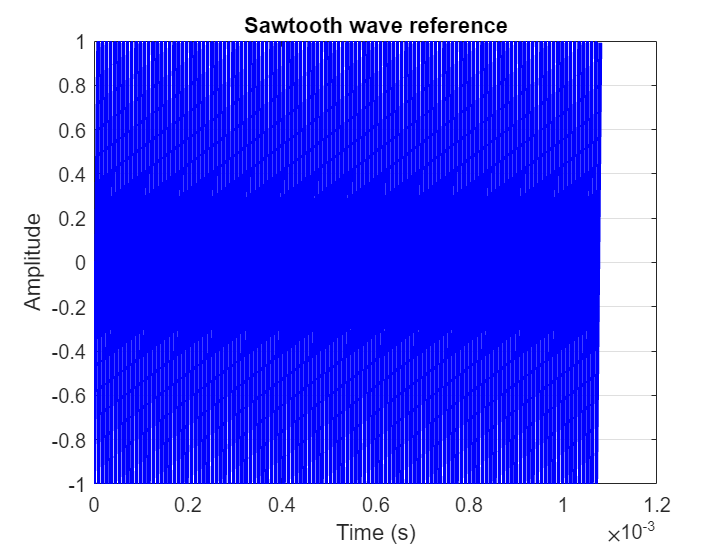

% Modulating multiplier is set as the ratio between the input signal
% frequency and the modulated signal frequency. In my opinion rather than
% setting two frequencies (both input sine wave and the modulation
% trianglar wave), that is a better idea coz the input is in the range from
% 20Hz to 20kHz
modulatingMultiplier = 40; 

sawtoothFrequency = modulatingMultiplier * sineFrequency; % Frequency in Hz
sawtoothNumPoints = sineNumPoints; % Number of data points, sync with the datapoint for I/P signal
sawtoothSamplingRate = sineSamplingRate; % Sampling rate in Hz, sync with the sampling rate for I/P signal
t = (0:sawtoothNumPoints-1) / sawtoothSamplingRate; % Define time axis

% Generate the sawtooth wave
sawtoothAmplitude = 1; % Amplitude of the sawtooth wave
sawtoothWaveReference = sawtoothAmplitude * sawtooth(2 * pi * sawtoothFrequency * t, 1);

% % Plot the sawtooth wave
figure();
plot(t, sawtoothWaveReference, "LineWidth", 2, "Color", "blue");
xlabel("Time (s)");
ylabel("Amplitude");
title("Sawtooth wave reference");
grid on;

## Class D modulation of the sine wave

outputVal = zeros(1,sineNumPoints);
 for i = 1:1:sineNumPoints
     if sawtoothWaveReference(i) <= sineWaveSignal(i)
         outputVal(i) = 1;
     else
         outputVal(i) = -1;
     end
 end

## Drawing out the figure that shows the modulation process

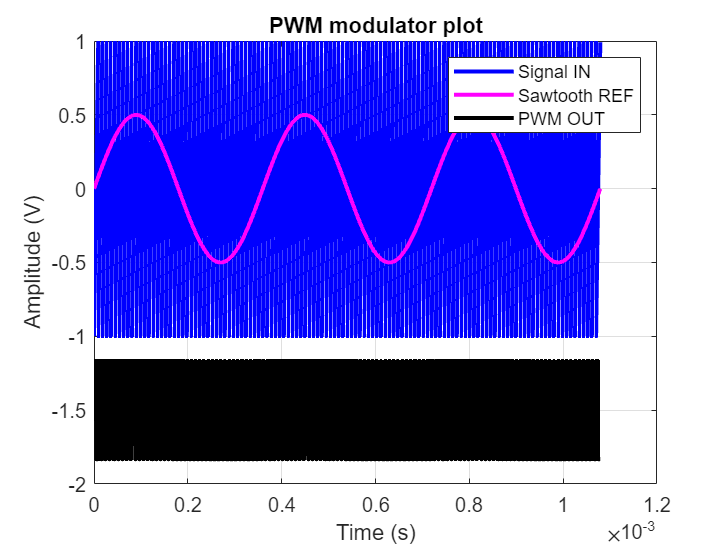

figure();
plot(t, sawtoothWaveReference, "LineWidth", 2, "Color", "blue"); % Sawtooth wave
hold on;
plot(t, sineWaveSignal, "LineWidth", 2, "Color", "magenta"); % Sine wave
hold on;
plot(t, outputVal ./ 3 - 1.5, 'LineWidth', 2, 'Color', "black"); % PWM output
xlabel("Time (s)");
ylabel("Amplitude (V)");
title("PWM modulator plot");
legend("Signal IN", "Sawtooth REF", "PWM OUT");
hold off;
grid on;

## PWM and filtering results

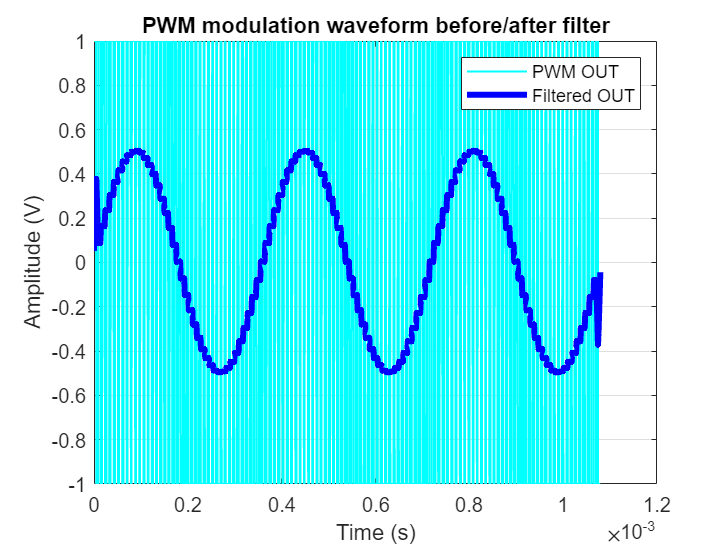

figure();
plot(t,outputVal,'LineWidth',1,'Color','cyan')

lowpass_output = lowpass(outputVal, 0.01);
second_lowpass_output = lowpass(lowpass_output, 0.01); % Filtering twice to get -40dB/decade
mean_output = movmean(second_lowpass_output, 500);

hold on;
plot(t, mean_output,'LineWidth',3,'Color','blue');
hold off;

grid on;
xlabel("Time (s)");
ylabel("Amplitude (V)");
legend("PWM OUT", "Filtered OUT");
title("PWM modulation waveform before/after filter");

## Comparison of the original signal and the reconstructed signal

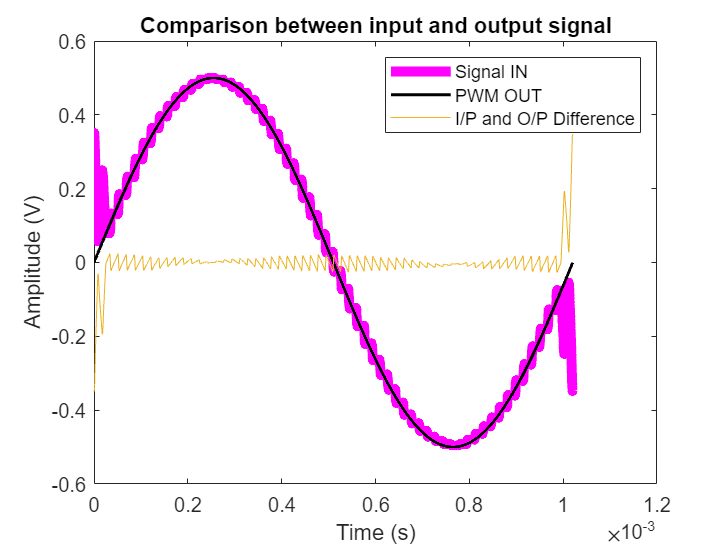

diffSignal = sineWaveSignal - mean_output;
plot(t, mean_output, "LineWidth", 5, "Color", "magenta");
hold on;
plot(t, sineWaveSignal, "LineWidth", 1.5, "Color", "black");
hold on;
plot(t, diffSignal);
hold off;
xlabel("Time (s)");
ylabel("Amplitude (V)");
legend("Signal IN", "PWM OUT", "I/P and O/P Difference");
title("Comparison between input and output signal");